接1002_1214,把测线改为1002.17

clear;
addpath fun\;
File_path = "F:\boshi\navigation code\202401\mit_data_watch\data\";
Filename_h5 = File_path + ...
    "Flt1002-train.mat";
feature_cur = {"CUR_COM1","CUR_ACHi","CUR_ACLo",...
    "CUR_TANK","CUR_FLAP","CUR_STRB",...
    "CUR_SRVO_O","CUR_SRVO_M","CUR_SRVO_I",...
    "CUR_IHTR","CUR_ACPWR","CUR_OUTPWR",...
    "CUR_BAT1","CUR_BAT2","V_BLOCK"};
cur_data = [];
for i=1:length(feature_cur)
    feature = feature_cur{i};
    load(Filename_h5,feature);
    data_temp = load(Filename_h5,feature);
    data_temp = getfield(data_temp, feature);
    cur_data = [cur_data data_temp];
end
features = {...
    "LINE","TIME","IGRFMAG1","COMPMAG1","FLUXB_X","FLUXB_Y","FLUXB_Z",...
    "PITCHRT","ROLLRT","YAWRT","INS_HGT"};

for i=1:length(features)
    feature = features{i};
    load(Filename_h5,feature);
end
feature_tfm = {"UNCOMPMAG3","UNCOMPMAG4","UNCOMPMAG5"};
tfm_data = [];
for i=1:length(feature_tfm)
    feature = feature_tfm{i};
    load(Filename_h5,feature);
    data_temp = load(Filename_h5,feature);
    data_temp = getfield(data_temp, feature);
    tfm_data = [tfm_data data_temp];
end

flight_temp = 1002.17;
x = [];
linet = flight_temp;
for i=1:length(linet)
    line_temp = linet(i);
    x_temp = find(LINE==line_temp);
    x = [x;x_temp];
end

STRB电流修复

diff_6 = diff(cur_data(x,6));
cur_6 = cur_data(x,6);
eps_2 = 0.1;
std_6 = 0.03;
index_6 = [];
for i=1:length(x)-1
    if (diff_6(i) > eps_2||diff_6(i) < -eps_2)
        index_6 = [index_6,i];
    end
end
range_6 = [];
for i=1:length(index_6)-1
    range_t = index_6(i):index_6(i+1);
    if (std(cur_6(range_t))>std_6)
        range_6 = [range_6,range_t];
    end
end
cur_strb_temp = CUR_STRB(x);
range_bool = false(length(x),1);
range_bool(range_6) = true;
t = 1:length(x);
cur_strb_temp(range_bool) = interp1(t(~range_bool),...
    cur_strb_temp(~range_bool), t(range_bool));
recover_strb = CUR_STRB(x)-cur_strb_temp;
range_6 = unique(range_6);

range_T = [];
for i=1:length(range_6)
    t = range_6(i);
    if (recover_strb(t) > -0.01)
        range_T = [range_T,i];
    end
end
x_opt = opt_data(recover_strb(range_6),range_T);

Optimal x: 0.2068
Minimum std_opt: 0.0069


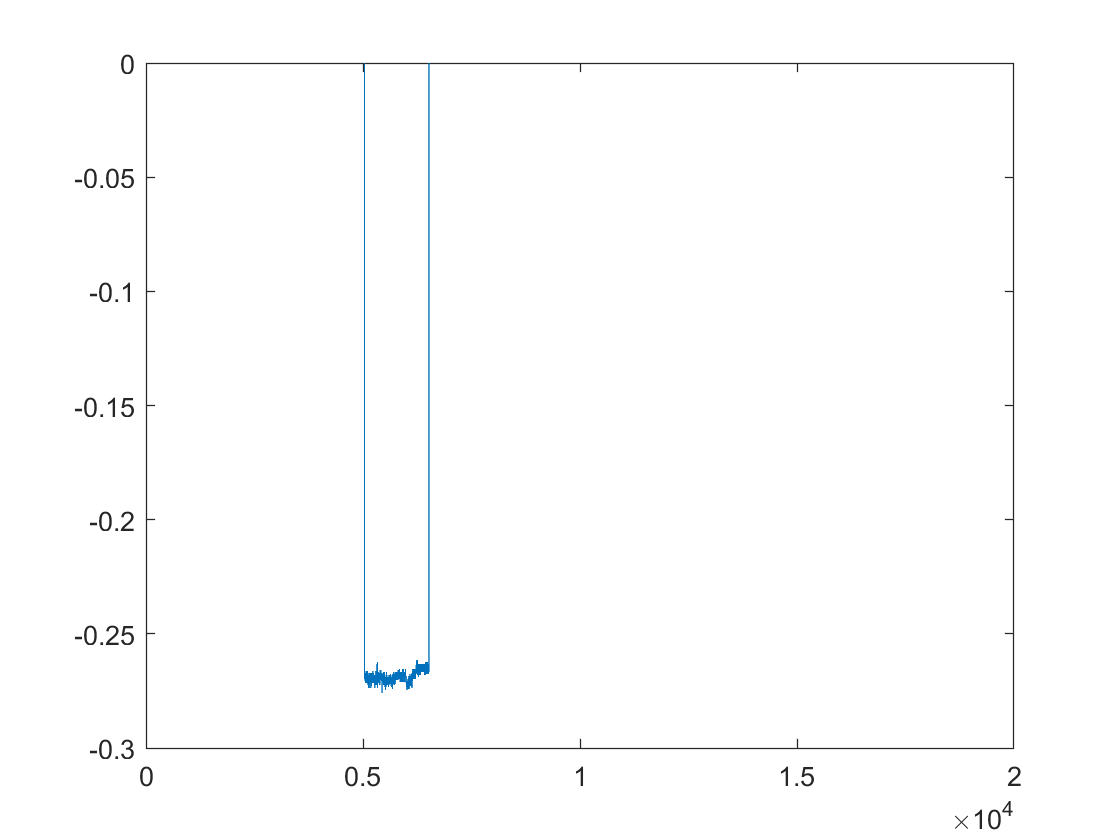

strb_fil = recover_strb;
history_t = [];
for i=1:length(range_6)
    t = range_6(i);
    if (recover_strb(t) > -0.01)
        strb_fil(t) = strb_fil(t) - x_opt;
        history_t = [history_t,t];
    end
end
range_bool2 = false(length(range_6),1);
history_t2 = [];
for i=1:length(range_6)
    t = range_6(i);
    if (strb_fil(t) > -0.2)
        history_t2 = [history_t2,i];
    end
end
range_bool2(history_t2) = true;
recover_strb2 = strb_fil(range_6);
t = 1:length(range_6);
recover_strb2(range_bool2) = interp1(t(~range_bool2),...
    recover_strb2(~range_bool2), t(range_bool2),'spline');
strb_fil2 = strb_fil;
delta_fil2 = mean(recover_strb2)*(3.5-2.5)/3.5;
strb_fil2(range_6) = recover_strb2 + delta_fil2;
figure;
plot(strb_fil2);

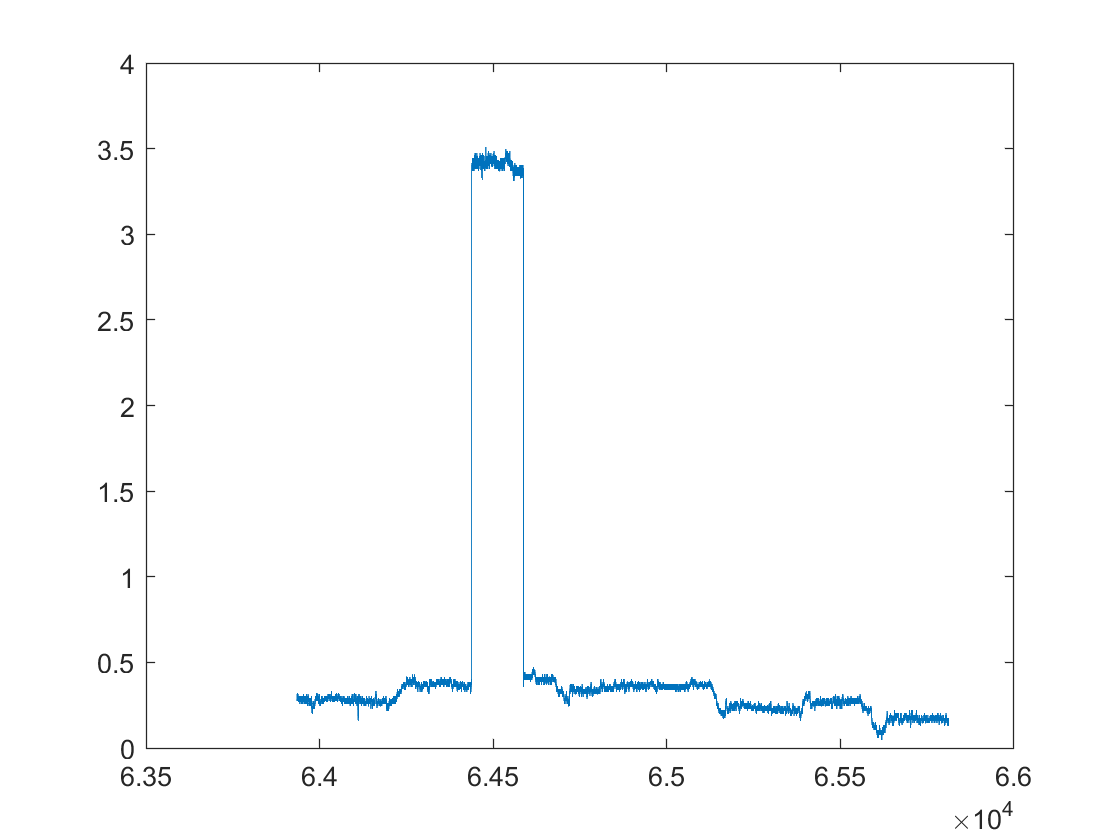

strb_fil3 = abs(normalize(cur_strb_temp+strb_fil2));
figure;
plot(TIME(x),strb_fil3);

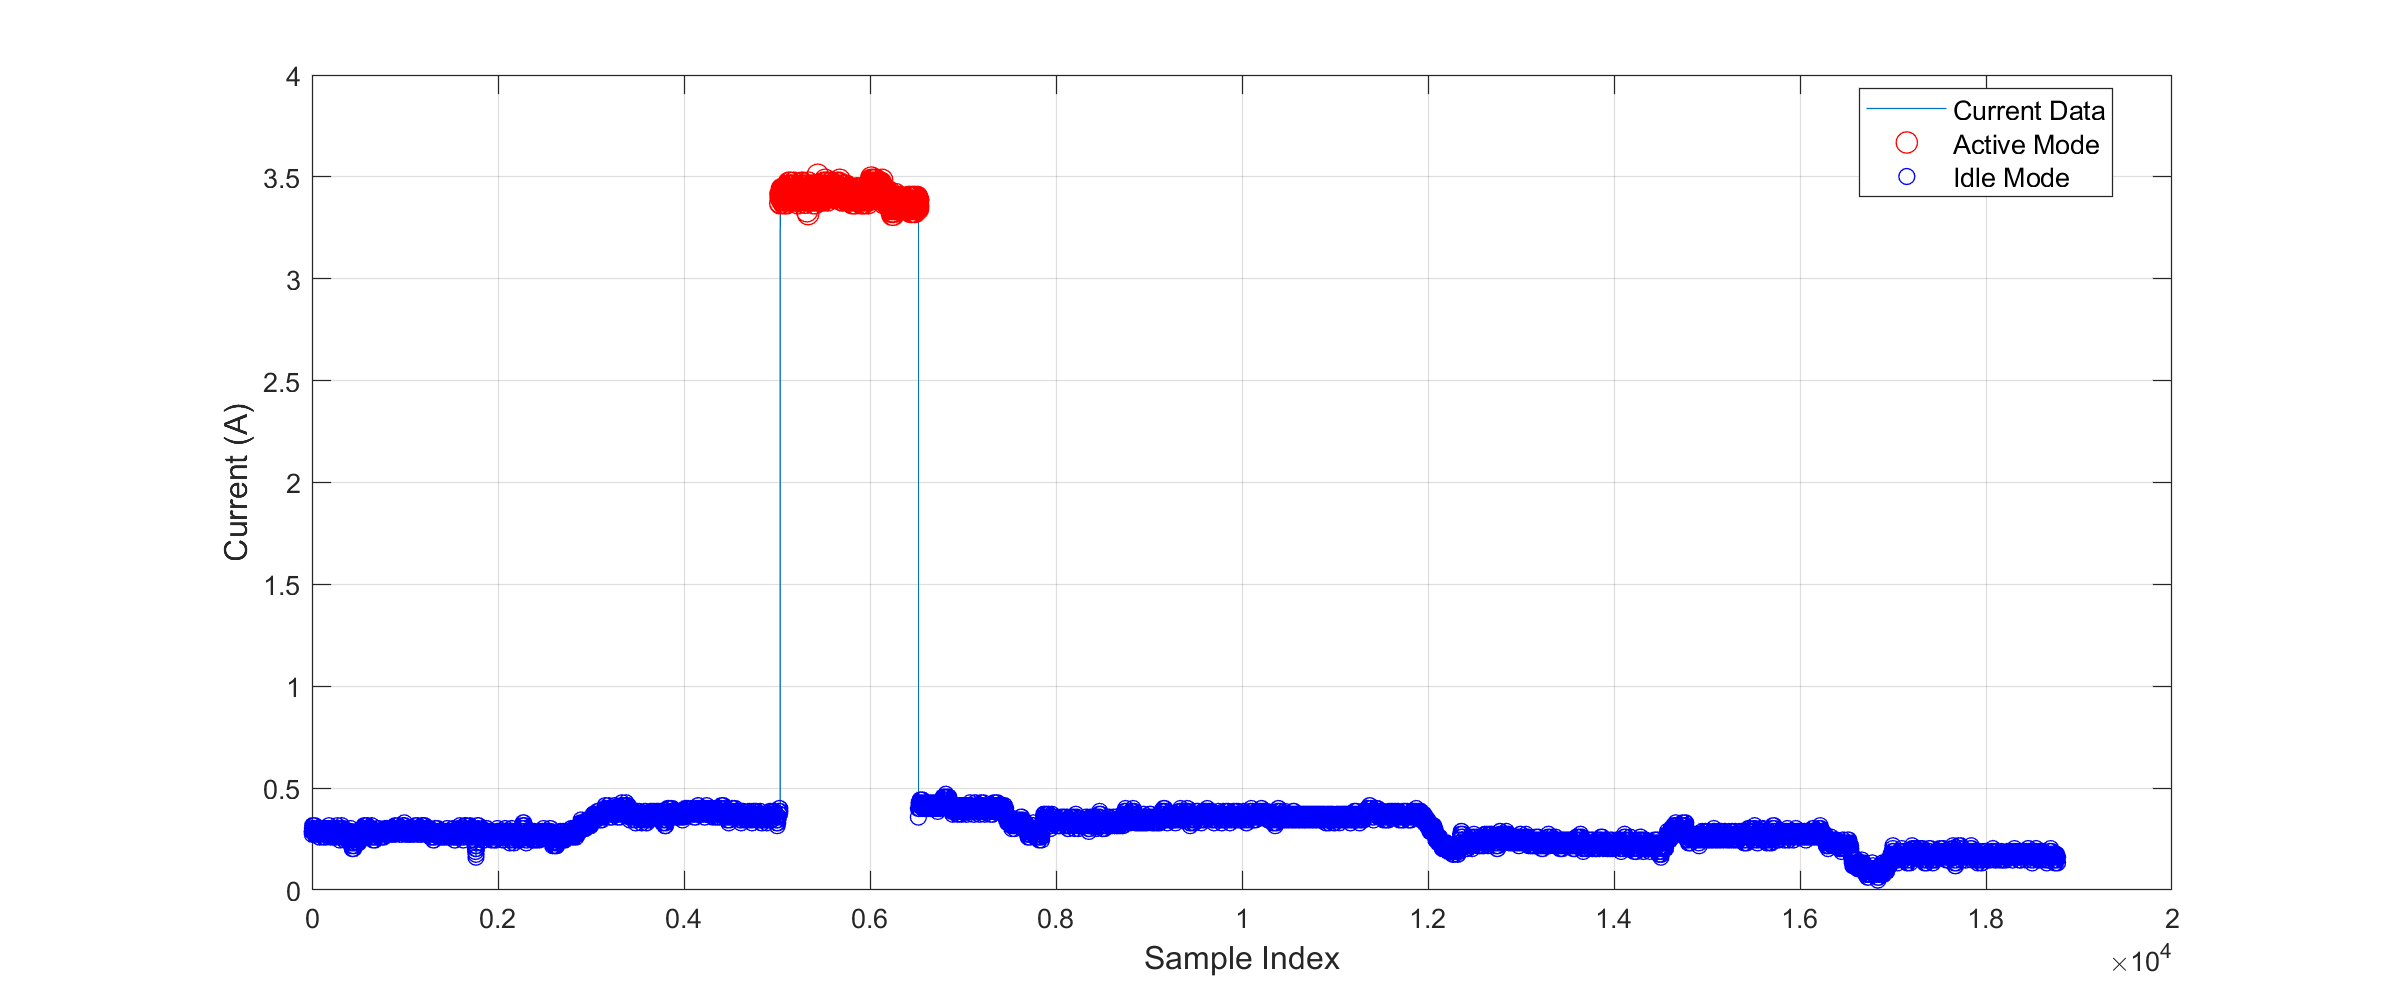

k = 6;
y = strb_fil3;
k_opt = 2;
GMModels = fitgmdist(y, k_opt, 'Replicates', 5); % GMM 拟合

addpath H:\boshi\navcode\202411\MIT_code\fun\classify;
x_plot = (1:length(y))'; % 横轴点索引
gmm_params.means = GMModels.mu; % 模态均值
gmm_params.variances = squeeze(GMModels.Sigma); % 模态方差
gmm_params.weights = GMModels.ComponentProportion; % 模态权重
[labels, posterior_probs] = classify_data_by_gmm(y, gmm_params, k_opt);

% 绘图
% 调整图片大小
figure;
set(gcf, 'Position', [100, 100, 1200, 500]); % 设置宽为1200像素
hold on;
plot(x_plot, y, 'DisplayName', 'Current Data'); % 所有点数据
plot(x_plot(labels == 2), y(labels == 2), 'ro', 'MarkerSize', 8, 'DisplayName', 'Active Mode'); % 红色标注
plot(x_plot(labels == 1), y(labels == 1), 'bo', 'MarkerSize', 6, 'DisplayName', 'Idle Mode'); % 蓝色标注，符号小一些
xlabel("Sample Index", 'FontSize', 12);
ylabel("Current (A)", 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10); % 将legend移动到右上角，避免遮挡数据
grid on;
box on;
hold off;

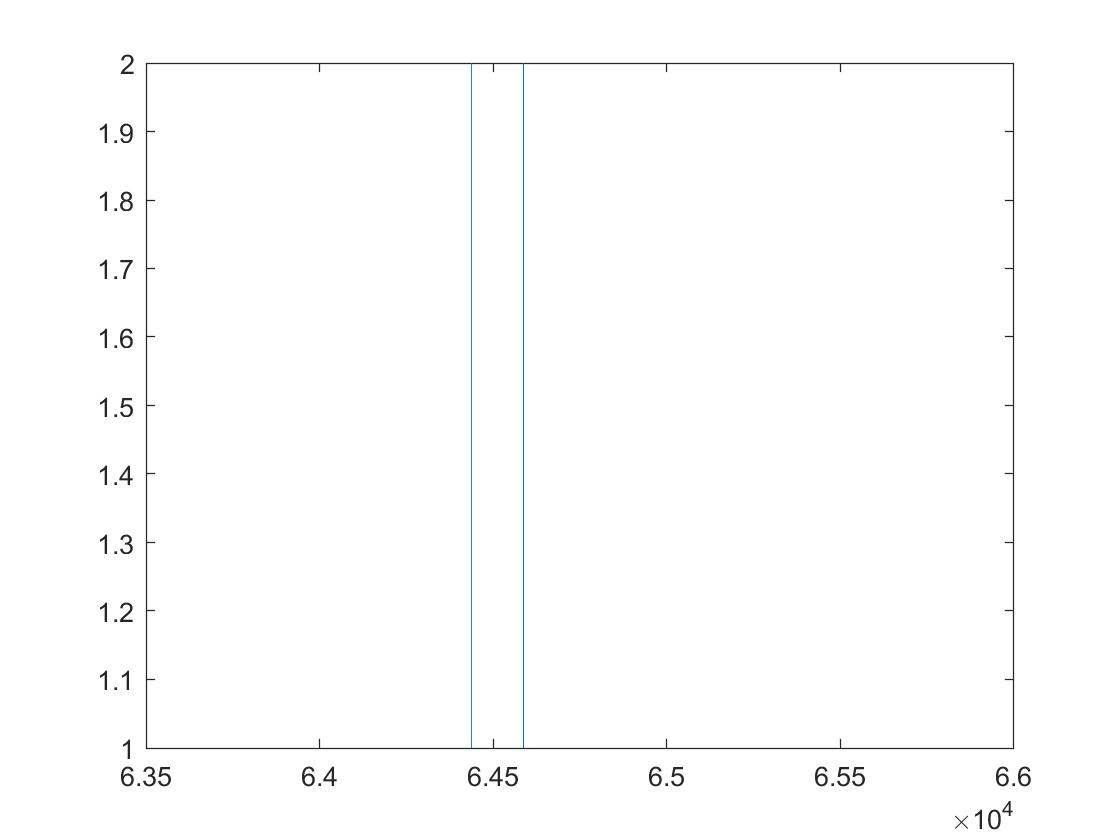

figure;
plot(TIME(x),labels);

计算准确率

TP=64580.2-64438.4;
FP=64430.01-63935;
FP2=65812-64586.8;
time_all=65812-63935;
ACC=(TP+FP+FP2)/time_all;

vX = FLUXB_X(x);
vY = FLUXB_Y(x);
vZ = FLUXB_Z(x);
[vCosX, vCosY, vCosZ] = calculate_cosine(vX, vY, vZ);
[vDCosX, vDCosY, vDCosZ] = calculate_derivate(vCosX, vCosY, vCosZ);
cur_norm = normalize(CUR_ACPWR(x));
[u4,~,info] = vmd(cur_norm,'NumIMF',6);
VMD_acpwr = flip(u4,2)';
ACPWR_Model = cal_elec(VMD_acpwr(1,:)',vCosX, vCosY, vCosZ);
STRB_Model = cal_elec(strb_fil2,vCosX, vCosY, vCosZ);
Model = [vCosX, vCosY, vCosZ, vCosX.^2, vCosX.*vCosY, vCosX.*vCosZ, vCosY.^2, vCosY.*vCosZ, ...
    vCosX.*vDCosX, vCosX.*vDCosY, vCosX.*vDCosZ, vCosY.*vDCosX, vCosY.*vDCosY, vCosY.*vDCosZ,...
    vCosZ.*vDCosX, vCosZ.*vDCosY,ACPWR_Model];

data_range = range_6;
range_index = false(1, length(x));
range_index(data_range) = true;

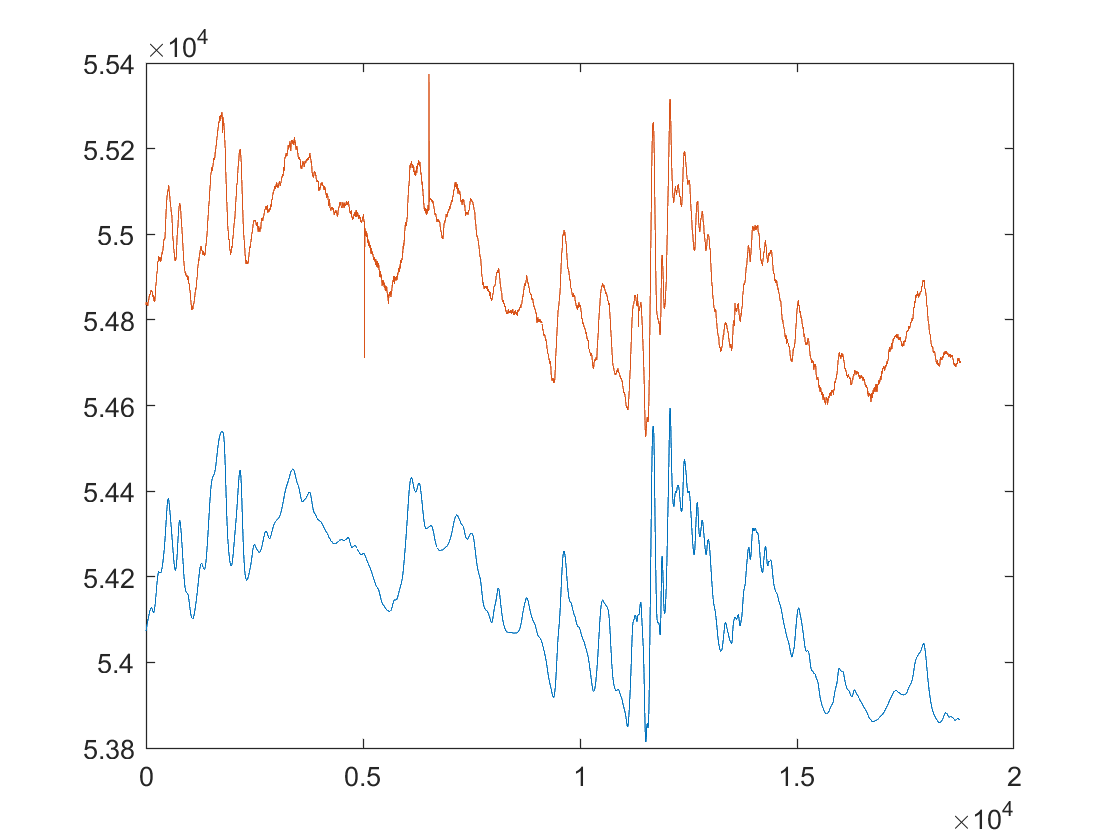

load("data\coeff\coeff_cur1216.mat");
load("data\coeff\coeff1218.mat");
vCompTotal41 = zeros(length(x),1);
vTotal_test = UNCOMPMAG4(x);
Model_test = Model;
STRB_Model_test = STRB_Model;
for i=1:length(x)
    if (~range_index(i))
        vCompTotal41(i) = vTotal_test(i) - Model_test(i,:)*vCfsCur;
    else
        vCompTotal41(i) = vTotal_test(i) - Model_test(i,:)*vCfsCur - STRB_Model_test(i,:)*vCfsCur2;
    end
end
figure;
plot(COMPMAG1(x));
hold on;
plot(vCompTotal41);

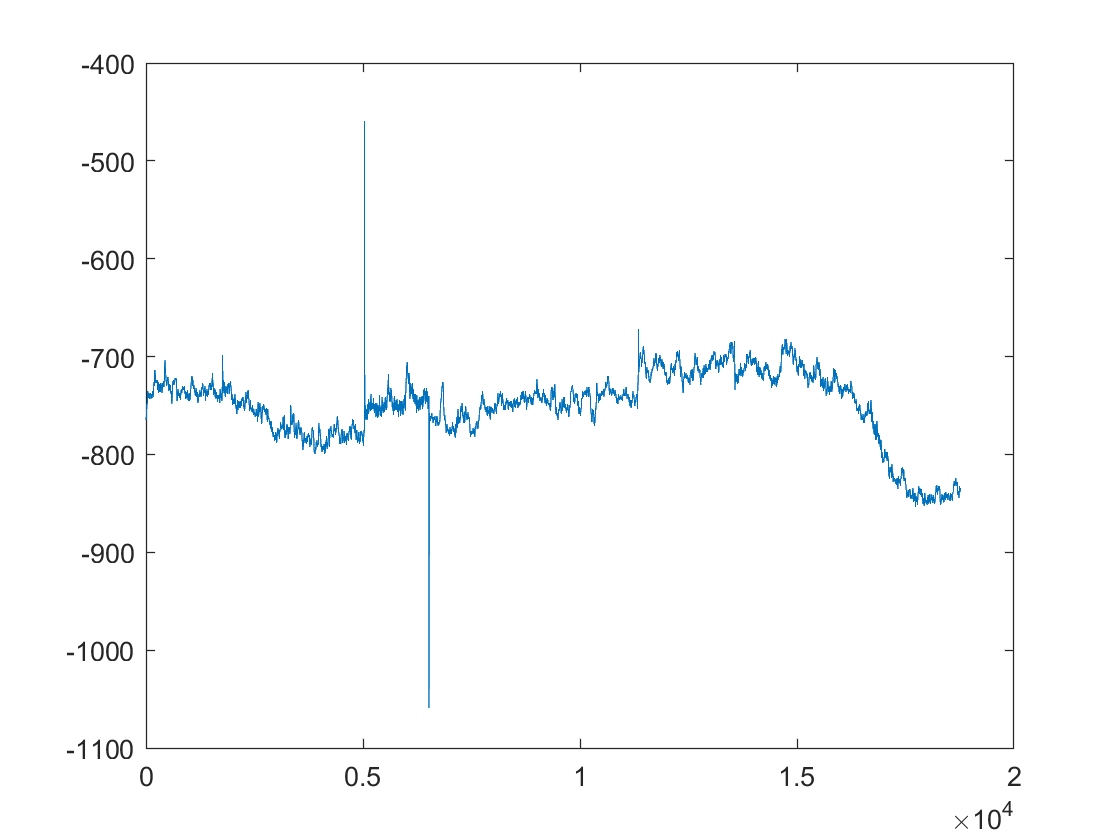

figure;
plot(COMPMAG1(x)-vCompTotal41);

delta_4 = COMPMAG1(x) - vCompTotal41;
std_4 = std(delta_4);
fprintf("std of delta 1:%f\n",std_4);

std of delta 1:36.522419


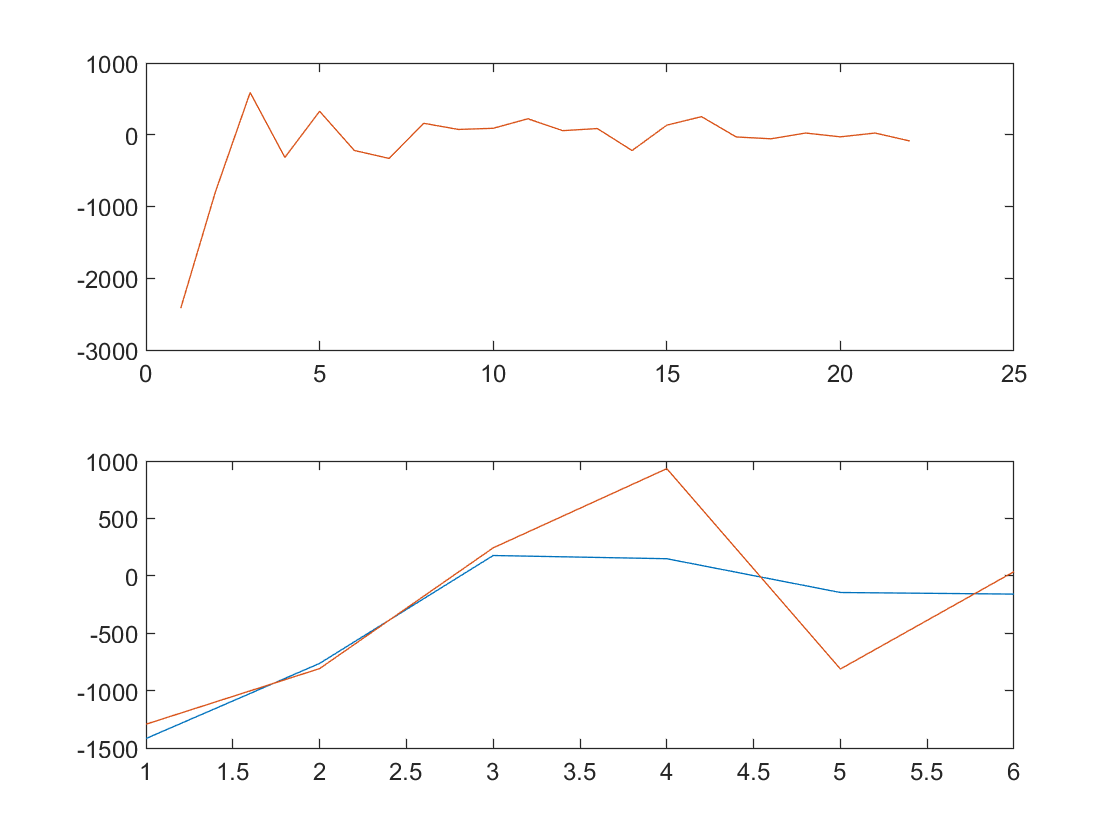

load("data\coeff\coeff_cur12152.mat");
vCfsCur_plot_1 = vCfsCur;
vCfsCur_plot_2 = vCfsCur2 ;
load("data\coeff\coeff_cur12143.mat");
figure;
subplot(2,1,1);
plot(vCfsCur_plot_1);
hold on;
plot(vCfsCur);
subplot(2,1,2);
plot(vCfsCur_plot_2);
hold on;
plot(vCfsCur2);

nn_flight_4 = load("MagNav\flight1002.txt");
nnComp_4 = UNCOMPMAG4-nn_flight_4(3:end)';
delta_4 = COMPMAG1(x) - nnComp_4(x);
std_4 = std(delta_4);
fprintf("std of delta 1:%f\n",std_4);

std of delta 1:48.219700


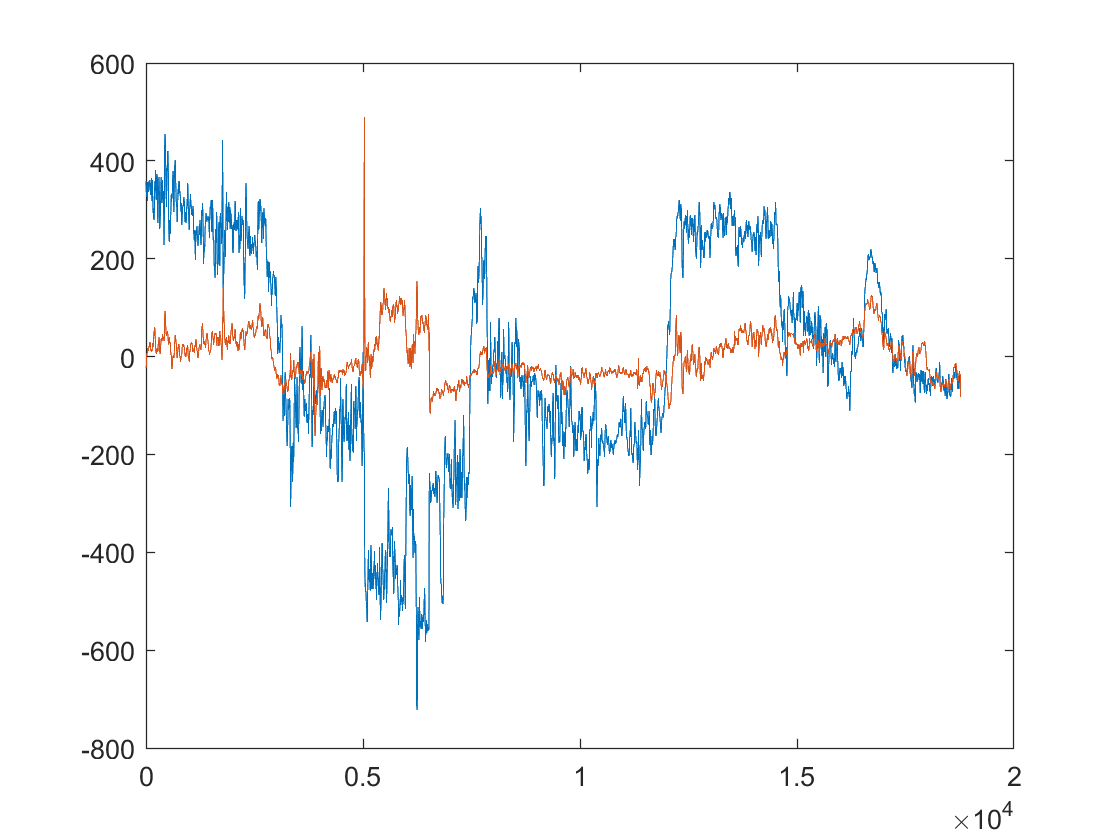

figure;
plot(detrend(COMPMAG1(x)-UNCOMPMAG4(x)));
hold on;
plot(detrend(delta_4));

std(COMPMAG1(x)-UNCOMPMAG4(x))

ans = 286.6157

std_t = [286.62,...
44.52,...
51.17,...
48.22,...
41.06,...
];
IR = zeros(length(std_t),1);
for i=1:length(std_t)
    IR(i) = std_t(1)/std_t(i);
end
6.44

ans = 6.4400

5.60

ans = 5.6000

5.94

ans = 5.9400

8.95

ans = 8.9500

保存补偿后的数据

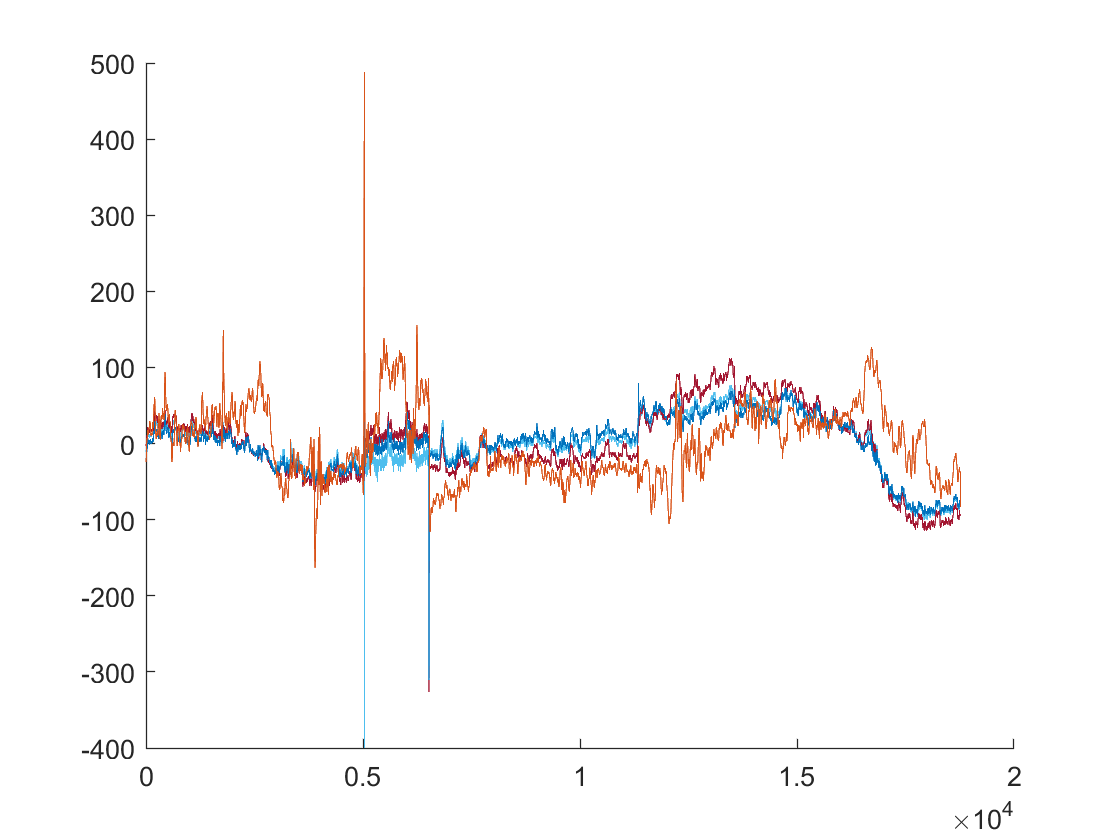

comp_data = zeros(length(x),4);
delta_data = zeros(length(x),4);
FileName_t = {"data\coeff\coeff_cur12144.mat",...
    "data\coeff\coeff_cur12145.mat",...
    "data\coeff\coeff_cur1216.mat"};
for j=1:length(FileName_t)
    load(FileName_t{j});
    vTotal_test = UNCOMPMAG4(x);
    Model_test = Model;
    STRB_Model_test = STRB_Model;
    for i=1:length(x)
        if (~range_index(i))
            comp_data(i,j) = vTotal_test(i) - Model_test(i,:)*vCfsCur;
        else
            comp_data(i,j) = vTotal_test(i) - Model_test(i,:)*vCfsCur - STRB_Model_test(i,:)*vCfsCur2;
        end
    end
    delta_data(:,j) = COMPMAG1(x)-comp_data(:,j);
end
comp_data(:,4) = nnComp_4(x);
delta_data(:,4) = COMPMAG1(x)-nnComp_4(x);
range_plot = [5035,6519];
figure;
hold on;
for i=1:size(comp_data,2)
plot(detrend(delta_data));end

y_lim3 = ylim;